# Exercise 3

## Visibility-Based Roadmap

### About This Exercise

The roadmap you created in the previous exercise relied on a cell decomposition. However, you can also make roadmaps directly from the obstacles without first doing a cell decomposition. In this exercise, you will use the vertices of the obstacles as the nodes and connect them according to what other nodes are directly visible. As our robot is not a point, we first need to create a buffer-zone around the obstacles so that the robot can safely travel to the nodes without any collisions. The goal is to create a graph just from the vertices of the obstacles.

**By the end of this exercise, you'll be able to: **

- **Create a "road map" of waypoints based on the position of obstacles, without the need for a cell decomposition.**

### Visibilty to Graph

You will create a function that takes in the obstacles, creates a buffer around the obstacles, sets all of the verticese of the buffered obstacles as nodes, and finally connects nodes according to what is visible.

[► Complete the visibliltyRoadmap function](matlab:open('./visibilityRoadmap.mlx'))

First we'll set up the obstacles that will be the input to the function.

lim = 4;
p1x = [-2  -1 1 2 1 -1];
p1y = [0 1 1 0 -1 -1]-1;
p2x = [-2 0 .5 -1];
p2y = [3 3 2 2];

obstacle(1).px = p1x;
obstacle(1).py = p1y;
obstacle(2).px = p2x;
obstacle(2).py = p2y;

### Visibility roadmap

Test your function here.

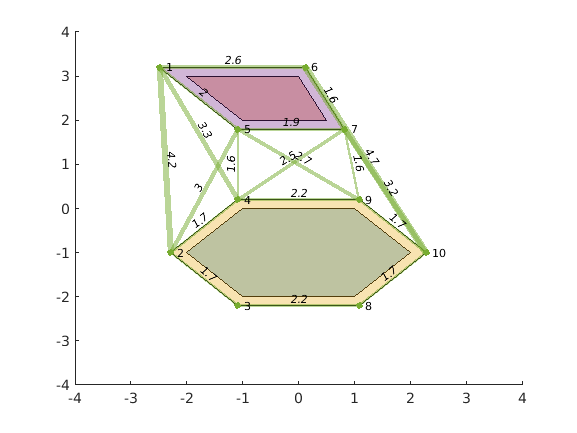

[G,A,nodes_xy,polyvec,polyvecbuf] = visibilityRoadmap(obstacle);

plotRoadmap(polyvec, polyvecbuf, lim, G, nodes_xy);

### Reduced visibility roadmap

By adding a second optional argument to your function, you change the algorithm to reduced visibility. Test that here. Does this roadmap seem better or worse, and why?

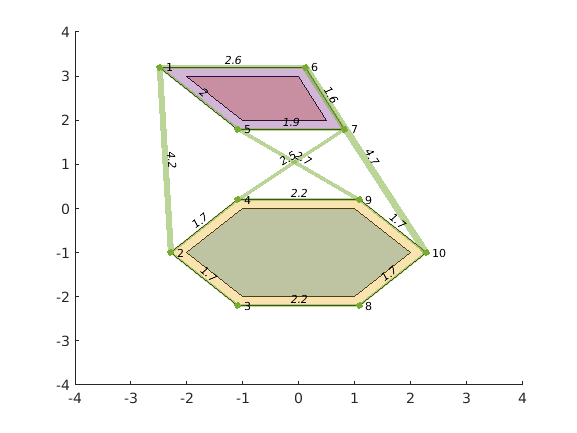

[G,A,nodes_xy,polyvec,polyvecbuf] = visibilityRoadmap(obstacle,1);

plotRoadmap(polyvec, polyvecbuf, lim, G, nodes_xy);

function plotRoadmap(polyvec, polyvecbuf, lim, G, nodes_xy)
figure;
plot(polyvec)
hold on
plot(polyvecbuf)
axis([-lim lim -lim lim])
LWidths = 5*G.Edges.Weight/max(G.Edges.Weight);
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)
end

### Finished!

This roadmap is simple and effective to implement, and the reduced version maintains coverage while reducing the number of edges. You also do not need to set any limits on your space, as you may assume there are no obstacles extending outwards. One potential drawback is that all of the nodes are close to obstacles, which may not always be desirable. Now that we have explored a couple of methods for making roadmaps, we need a way to decide which roads to take given starting and goal nodes. We'll explore graph search algorithms in the next exercise.